# Just-Intonation vs. Equal Temperament Examples

## Playing a Major Triad

Description of first code block

A_EqualTemp = [440, 554.3633, 659.2551];
A_JustInt   = [440, 550, 660];
duration = 1;
amp = 2;
playNotes(A_EqualTemp, duration, amp);
pause(duration - .1)
playNotes(A_JustInt, duration, amp);


## Playing a Minor Triad

Description of second code block

Am_EqualTemp = [440, 523.25, 659.2551];
Am_JustInt   = [440, 528, 660];
duration = 1;
amp = 2;
playNotes(Am_EqualTemp, duration, amp);
pause(duration - .1)
playNotes(Am_JustInt, duration, amp);


## Playing Overtone Series in Equal Temperament

Description of second code block

EQ_Tones = generateETNotes(1, 88);

tone_index = 20;
per_note_time = 1.5/3;
hold_out_time = 2;
jumps = [0, 12, 19, 24, 28, 31, 34, 36, 38, 40, 42];
end_index = length(jumps);

for i = 1:end_index
    playNotes(EQ_Tones(tone_index + jumps(i)), per_note_time*(end_index-i+1)+hold_out_time, 5)
    pause(per_note_time)
end


## Playing Overtone Series in Just Intonation

Description of second code block

EQ_Tones = generateETNotes(1, 88);

base_tone = EQ_Tones(20);

per_note_time = 1.5/3;
hold_out_time = 2;
num_jumps = 12;

for i =1:num_jumps
    playNotes(base_tone*i, per_note_time*(num_jumps-i+1)+hold_out_time, 5)
    pause(per_note_time)
end



## Testing abritrary note combos with our algorithm

Description of first code block

low_index = -3;
high_index = 88;
[ET_notes, ET_tolerance_bands] = generateETNotes(low_index,high_index);

%Chord_indexes = [40, 42, 46];
Chord_indexes = 13.+[0, 12, 19, 24, 28, 31, 34, 36, 38, 40, 42];
%Chord_indexes = [49, 53, 56];  %A major chord
EQ_freqs = zeros(1, length(Chord_indexes));
for i=1:length(Chord_indexes)
    EQ_freqs(i) = EQ_Tones(Chord_indexes(i));
end
JI_freqs = Algorithm1(Chord_indexes, ET_notes, ET_tolerance_bands, (low_index-1))

Elapsed time is 0.002998 seconds.


JI_freqs =    55.0000  110.0000  165.0000  220.0000  275.0000  330.0000  385.0000  440.0000  495.0000  550.0000  605.0000


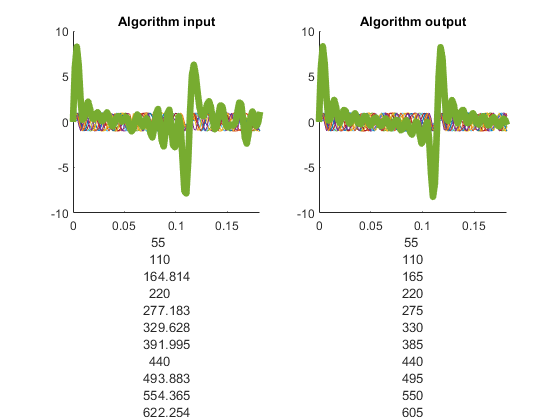

duration = 4;
amp = 5;
fig = figure;
plotWaves(EQ_freqs, JI_freqs, fig)

playNotes(EQ_freqs, duration, amp);
pause(duration - .2)
playNotes(JI_freqs, duration, amp);
